Testing

clear all;
%indexing starts at 1
fig1=figure()

fig1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


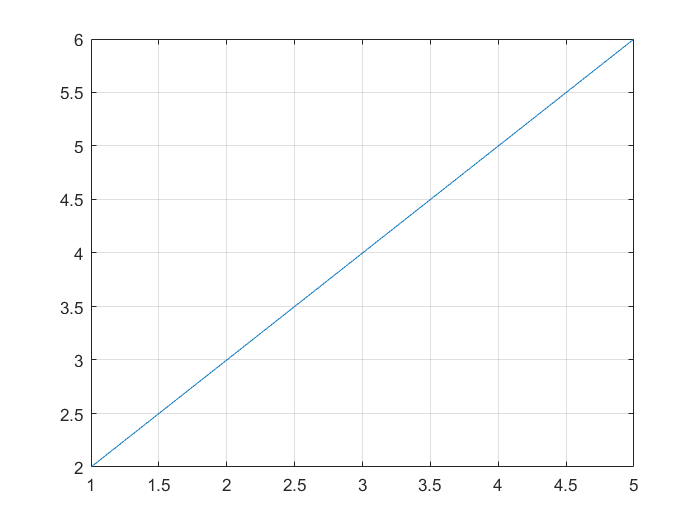

plot(1:5,2:6)
grid


fig2=figure()

fig2 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


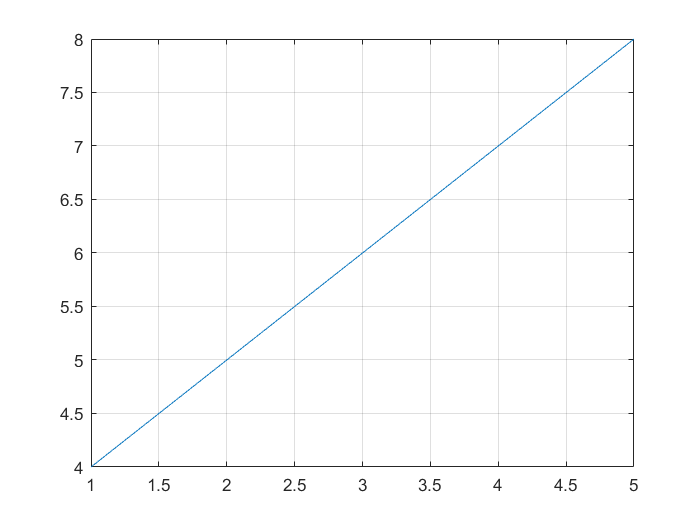

plot(1:5,4:8)
grid

1. Random Spins and Magnetization

m=zeros(1,3);

% 3x3 random spins
S1=randi([0 1],3,3);
S1(S1==0)=-1

S1 =      1     1    -1
     1    -1     1
    -1    -1    -1


m(1)=sum(sum(S1))/numel(S1)

m =    -0.1111         0         0



% 10x10 random spins
S2=randi([0 1],10,10);
S2(S2==0)=-1

S2 =      1     1    -1     1     1    -1    -1     1    -1    -1
     1    -1    -1    -1     1    -1     1    -1    -1    -1
    -1    -1     1     1     1    -1    -1     1    -1    -1
     1    -1    -1    -1     1    -1     1     1     1     1
     1    -1     1    -1     1     1    -1    -1     1     1
    -1    -1     1    -1     1     1     1    -1    -1     1
     1    -1    -1     1     1     1     1     1    -1    -1
    -1    -1     1     1    -1    -1    -1    -1     1    -1
    -1    -1     1    -1    -1    -1     1     1    -1     1
     1     1     1    -1     1    -1     1     1     1     1


m(2)=sum(sum(S2))/numel(S2)

m =    -0.1111         0         0



% 64x64 random spins
S3=randi([0 1],64,64);
S3(S3==0)=-1

S3 =     -1     1    -1    -1     1     1     1     1     1    -1    -1     1     1     1    -1    -1    -1     1    -1     1    -1     1     1    -1     1    -1    -1    -1     1    -1    -1    -1    -1     1    -1     1    -1     1    -1    -1     1    -1    -1     1     1    -1     1    -1    -1     1
    -1    -1    -1    -1     1     1     1     1    -1    -1     1    -1    -1     1    -1     1     1     1     1    -1     1     1    -1     1     1    -1    -1     1     1     1     1     1    -1     1    -1     1    -1    -1     1    -1    -1     1     1     1    -1    -1     1    -1    -1     1
    -1    -1    -1    -1     1     1     1    -1    -1    -1    -1    -1     1     1     1    -1     1     1     1    -1     1    -1     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1     1     1    -1     1    -1     1    -1     1     1    -1     1     1    -1    -1     1
     1    -1    -1    -1     1     1    -1     1     1     1     1     1     1     1     1  

m(3)=sum(sum(S3))/numel(S3)

m =    -0.1111         0    0.0029



dispersion=(sum(m.^2)/numel(m))-(sum(m)/numel(m))^2

dispersion = 0.0028

2. Problem 2

L=3;    %length of spin matrix
N=2;    %total number of iterations
S = randi([0 1], L,L);
S(S==0)=-1;
S

S =     -1    -1     1
    -1     1     1
     1     1     1


M=zeros(1,N)

M =      0     0


Mbar=zeros(1,N)

Mbar =      0     0


E=zeros(1,N)

E =      0     0


Ebar=zeros(1,N)

Ebar =      0     0



%E(n)=(-1)*J*sum(spins*otherspins)
%look at notes again for details

for n=(1:N)
    a=randi([1 numel(S)])
    spinsum=0;
    %sum adjacent spins, multiply,
    %check sign
    
    if a<=L
        spinsum=spinsum+S(a+L)+S(L*(L-1)+a);
    elseif a>L*(L-1)
        spinsum=spinsum+S(a-L)+S(a-(L*(L-1)));
    else
        spinsum=spinsum+S(a-L)+S(a+L);
    end
    if mod(a,L)==1 %top row
        spinsum=spinsum+S(a+1)+S(a+L-1);
    elseif mod(a,L)==0 %bottom row
        spinsum=spinsum+S(a-1)+S(a-L+1);
    else
        spinsum=spinsum+S(a-1)+S(a+1);
    end
    spinsum
    
    %compare signs, flip
    if spinsum*S(a)<0
        S(a)=(-1)*S(a);
    else %~50/50 chance, check notes later
        S(a)=S(a)*((-1)^randi([0 1]));
    end
    S
    
    M(n)=sum(sum(S))/numel(S)
    Mbar(n)=sum(M)/n
    
    %wtf is J? whatever, just remember
    %to put it in later
    E(n)=0;
    for j=(1:L)
        for k=(1:L)
            if j<L
                E(n)=E(n)-(S(j,k)*S(j+1,k));
            else
                E(n)=E(n)-(S(j,k)*S(1,k));
           end
           if k<L
               E(n)=E(n)-(S(j,k)*S(j,k+1));
           else
               E(n)=E(n)-(S(j,k)*S(j,1));
           end
        end
    end
    %remember to multiply by J
    E(n)
    Ebar(n)=sum(E)/n
end

a = 1

spinsum = 0

S =     -1    -1     1
    -1     1     1
     1     1     1


M =     0.3333         0


Mbar =     0.3333         0


ans = -2

Ebar =     -2     0


a = 3

spinsum = 0

S =     -1    -1     1
    -1     1     1
    -1     1     1


M =     0.3333    0.1111


Mbar =     0.3333    0.2222


ans = -2

Ebar =     -2    -2
